# Visualizing Multidimensional Data

So far in this module you've learned about some common statistical distributions as well as techniques for describing a variable's distribution through histograms and descriptive statistics. By visualizing two or more variables at a time, however, you can better understand and identify relationships between variables and groups of observations in your data. In this script, you'll first see how some common distributions generalize to multiple dimensions while learning how to visualize two or more variables using *multidimensional* visualizations.

## The 2D Uniform Distribution

In a previous video you learned about the [uniform distribution](https://en.wikipedia.org/wiki/Uniform_distribution_(continuous)). A *standard* uniformly distributed variable $X$ has values evenly spread through the interval $[0,1]$, but in general, these values are evenly spread between any two bounds $X_{min}$ and $X_{max}$. Run the code below to generate a pair of uniformly distributed variables and visualize their distribution using a [2D histogram](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.histogram2.html).  

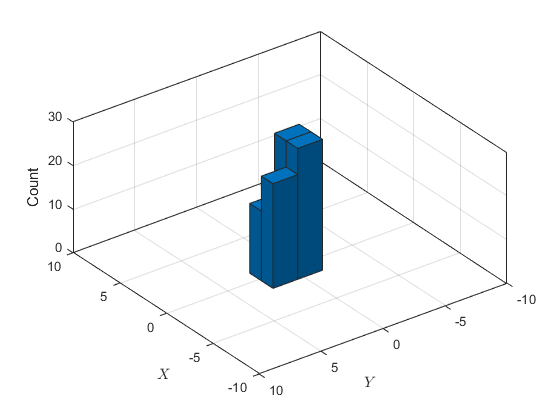

m = 100; % # of data points
xmin =-1.5; % lower X bound
ymin =-1.5; % lower Y bound
xmax =1; % upper X bound
ymax =2.5; % upper Y bound
X = rand([m,2]).*[xmax-xmin, ymax-ymin]+[xmin,ymin]; % generate X and Y
% Generate and label the 2D histogram
histogram2(X(:,1),X(:,2),'NumBins',2,...
                         'XBinLimits',[xmin,xmax],...
                         'YBinLimits',[ymin,ymax]);
xlabel('$X$','Interpreter','latex'); 
ylabel('$Y$','Interpreter','latex'); 
zlabel('Count');
xlim([-10 10]); ylim([-10 10]);

**Note: **The Rotate control can be helpful when viewing a 3D figure. 

- Click into the plot, then select 'Rotate'. 

- Rotate the plot by clicking and dragging the figure, or by right-clicking and selecting the desired axis view: X-Y, X-Z, or Y-Z.

Use the controls to:

- Modify the bounds of $X$ and $Y$

- Increase or decrease the number of data values, `m`

- Increase of decrease the number of bins

How do these options affect the histogram appearance? Which settings make it make it easier to tell the values are uniformly distributed? More difficult?

## The 2D Normal Distribution

The [normal (Gaussian) distribution](https://en.wikipedia.org/wiki/Normal_distribution) also has a [multivariate analog](https://en.wikipedia.org/wiki/Multivariate_normal_distribution). Run the code below to generate two normally distributed variables in two dimensions. This time, the distributions are visualized using the [`binscatter`](https://www.mathworks.com/help/matlab/ref/binscatter.html) function, which creates a binned scatter plot. Like 2D histograms, binned scatter plots count the number of datapoints in each box of a rectangular grid. The counts are visualized using box color instead of bar height.

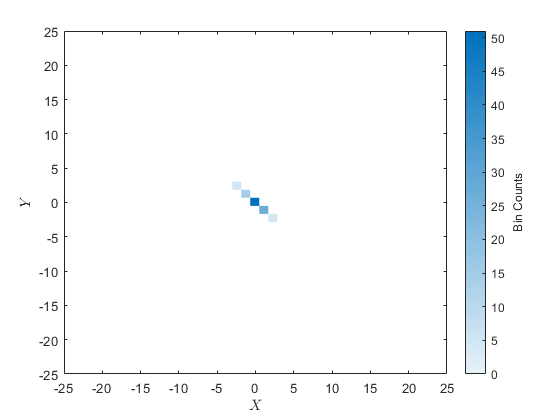

m = 100; % # of data points
mux =0; % X-mean
muy =0; % Y-mean
sigmax =1; % X-std
sigmay =1; % Y-std
bins = 50; % # of bins
c = -1; % correlation coefficient
X = mvnrnd([mux,muy], [sigmax^2, c*(sigmax*sigmay); c*(sigmax*sigmay), sigmay^2], m);
binscatter(X(:,1),X(:,2),bins);
xlim([-25 25]); ylim([-25 25]);
xlabel('$X$','Interpreter','latex'); 
ylabel('$Y$','Interpreter','latex');

Use the controls above to modify the mean and standard deviation of the $X$ and $Y$ variables, and to increase or decrease the number of bins used. How does each affect the resulting plot?

### Adding correlation

Recall that the [Pearson correlation coefficient](https://en.wikipedia.org/wiki/Correlation_coefficient) measures the strength of the linear relationship between two variables. A value of 0 indicates no linear relationship, and a value of +/- 1 indicates a perfect linear relationship (i.e. all data points lie on a single line). Use the control above to increase or decrease the correlation between $X$ and $Y$. What effect does correlation have on the distribution? 

## Mixed Distributions

Two variables often come from different distributions. An example is shown below using a normally distributed variable $X$ and [Rayleigh-distributed](https://en.wikipedia.org/wiki/Rayleigh_distribution) variable $Y$. Run the code below to generate the variables and visualize their distribution using a [scatter histogram](https://www.mathworks.com/help/matlab/ref/scatterhistogram.html). Scatter histograms combine a scatter plot with individual histograms for each variable. 

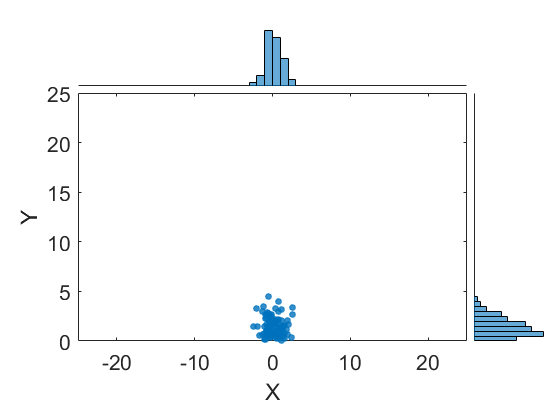

m = 100; % # of data points
mu =0; % normal distribution mean
sigma =1; % normal distribtuion standard deviation
b =1.25; % Rayleigh distribution skewness
x = random('Normal',mu,sigma,[m,1]); % Generate X 
y = random('Rayleigh',b,[m,1]); % Generate Y 
scatterhistogram(x,y,"XLabel","X","YLabel","Y",'FontSize',16,...
                     'MarkerSize',20,... % marker size
                     'MarkerAlpha',0.8,... % marker transparency
                     'MarkerFilled',"on",... % solid or hollow markers
                     'HistogramDisplayStyle',"bar"); % histogram type  
xlim([-25 25]); 
ylim([0 25]);

Try adjusting the standard deviation and skewness parameters. Note how the histograms make it easier to tell the distributions apart.

### Modifying visualization options

While the default settings for MATLAB visualization functions like `scatterhistogram` are usually adequate, for certain datasets it may be helpful to modify them for clarity, or you may have personal or organizational preferences. Plot options can be modified by supplying additional name-value pairs as input arguments. Several additional controls have been provided in the code above to adjust the histogram and scatter plot properties, and to change the histogram display style. You can find more information about the available options in the `scatterhistogram` documentation. Which combinations work best for large datasets? Small datasets? For telling distributions apart?

## Visualizing Continuous Variables

In the next few sections you'll use multidimensional visualizations to explore the Patients blood pressure study data. 

### Load the Patients dataset and generate a scatter histogram

The Patients dataset includes: weight, height, age, systolic and diastolic blood pressure, gender, smoker status, self-assessed health status, and the study location. You've already seen how to visualize the distributions of two continuous variables using a 2D histogram, binned scatter plot, and a scatter histogram. Run the code below to load the patient data into a `table` and create a scatter histogram of `Weight` and `Height`.

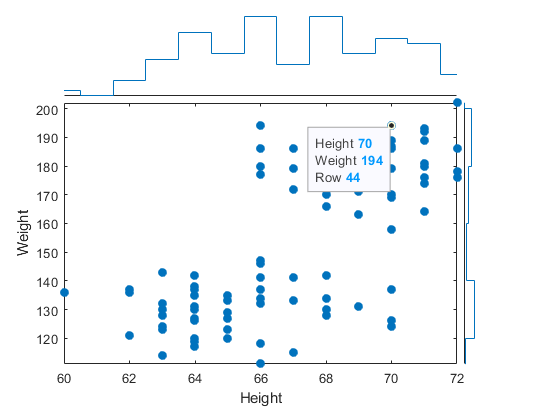

load patients
tbl = table(Weight,Height,Age,Systolic,Diastolic,Gender,Smoker,Location);
tbl.SelfAssessedHealthStatus = categorical(SelfAssessedHealthStatus,{'Excellent','Good','Fair','Poor'});
clearvars -except tbl
scatterhistogram(tbl,'Height','Weight');

The scatter plot indicates that `Weight` and `Height` seem to be positively correlated. Furthermore, the data seems to be separated into two distinct clusters of values. While the tendency of weight to increase with height has an obvious physical reason, the clustering of observations indicates the effect of another variable. 

### Adding a group variable to a scatter histogram

To determine if one of the discrete variables is responsible for the clustering you observed, you can specify a group variable in a scatter histogram. Use the control below to plot `Height` and `Weight` using different group variables. Do any help explain the clusters?

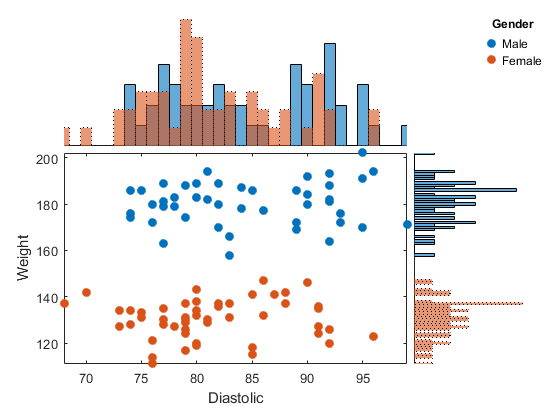

scatterhistogram(tbl,'Diastolic','Weight',...
                    'GroupVariable','Gender',...
                    'LegendVisible','on',...
                    'ScatterPlotProportion',0.6,...
                    'HistogramDisplayStyle',"bar");

It appears that the clusters in the `Height`-`Weight` data correspond to `Gender` groups. Use the controls to select different combinations of continuous variables. Can you find other clusters in the data? If so, is there a discrete variable that explains the grouping?

## Visualizing Discrete Variables

You've seen that scatter plots, histograms, and combinations of the two are common ways to visualize the distributions of continuous variables. But what about discrete variables? 

### Visualizing discrete data using heat maps

One way to visualize discrete data is to use a [heat map](https://www.mathworks.com/help/matlab/ref/heatmap.html), where the group combinations of two discrete variables are represented in a rectangular grid. Similar to binned scatter plots, the rectangle color is determined by the number of observations belonging to the corresponding pair. Run the code below to visualize the distributions of `Smoker` and `SelfAssessedHealthStatus`. Note that higher counts are indicated by darker colors. 

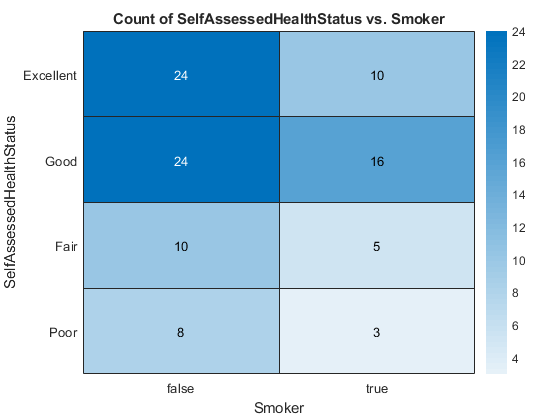

heatmap(tbl,'Smoker','SelfAssessedHealthStatus');

The patients are not evenly distributed about the group pairs, with more patients being no-smokers claiming above average ('Good' or 'Excellent') health, and far fewer being smokers claiming below average health. Use the controls to visualize the distributions of different combinations of discrete variables. What are the most common group pairs for each variable combination? The least common? How might uneven distributions due to over or under-represented groups or group pairs affect the conclusions you might draw from the data?

### Using a continuous variable to color a heat map

You can add information from a continuous variable to a heat map of discrete variables by specifying a 'color variable'. Instead of observation counts, the colors of each rectangle are determined by a computing a statistic using the color (continuous) variable values belonging to each discrete group pair. For example, you can compute the mean blood pressure of the three smokers rating their health poor, the 5 smokers rating their health fair, and so on. Using a color variable provides a way to visualize the group statistics you have previously calculated using the [`groupsummary`](https://www.mathworks.com/help/matlab/ref/double.groupsummary.html) function. Run the code below to compute the mean systolic blood pressure value for the different smoker and health status combinations.

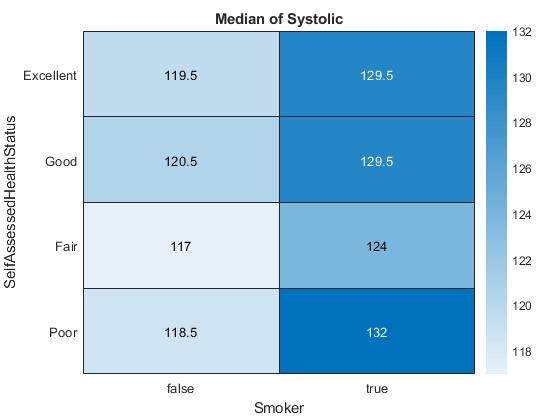

heatmap(tbl,'Smoker','SelfAssessedHealthStatus',...
            'ColorVariable',"Systolic",...
            'ColorMethod', "median");                                               

From the results, it seems like smokers have higher systolic blood pressure than non-smokers, but these values don't differ by self-assessed health status. However, conclusions like these should be weighted by the number of observations used to compute the statistics. That is, if there are only a few observations belonging to a given group, the statistic has a higher chance of being affected by mistakes or outliers. Look again at the number of observations used to compute the mean values by changing the color method to '`count`'. How confident are you that the statistics computed for each group pair represent their 'true' value (i.e. the value of the general population)? 

Try visualizing different combinations of discrete and continuous variables. Can you find any interesting differences between subgroups? How confident are you that these differences exist?

## Visualizing High Dimensional Datasets

Plotting only two variables at a time (known as *slicing*) can quickly become tedious with datasets containing many variables. It also becomes more difficult to identify relationships or clusters across more than two dimensions. Two methods for visualizing high-dimensional datasets which attempt to address these problems are discussed below.

### Generating a scatter plot matrix

Instead of generating a scatter plot for each continuous variable combination, it's possible to generate a[ matrix of scatter plots ](https://www.mathworks.com/help/stats/gplotmatrix.html)for *all* combinations at once. Each plot in the grid corresponds to a variable combination, with histograms of each variable shown on the diagonal. Run the code below to create a scatter plot matrix of the continuous patient variables. 

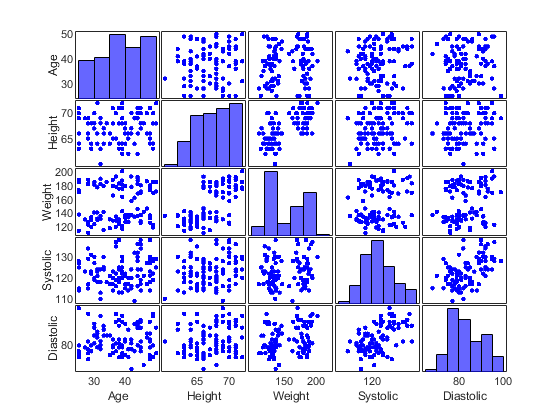

contvars = ["Age", "Height", "Weight", "Systolic", "Diastolic"];
X = tbl{:,contvars};
gplotmatrix(X,[],[],[],[],[],[],'hist',contvars)

Discrete variables can also be specified as grouping variables. Use the controls to select a grouping variable and modify the type of plot shown on the diagonal.

**Note:**

- Data must be supplied to `gplotmatrix` as a matrix, which is the reason for first extracting the continuous variables into `X`. 

- Labels are added to the plot by supplying the variable names as an additional input. 

- Each combination appears twice in the grid with the $X$ and $Y$ axes flipped.

### Creating a parallel coordinate plot

Scatter plot matrices generate individual plots for each variable combination. While this is more convenient than generating multiple plots, you are still only seeing two variables in any given plot. Another way to visualize high dimensional datasets is to create a [parallel coordinate plot](https://www.mathworks.com/help/matlab/ref/parallelplot.html), where *all* of the variables and observations are represented at once in a single plot. The trick is to use *multiple axes- *one for each variable. Run the code below to generate a parallel coordinate plot of the blood pressure variables.  

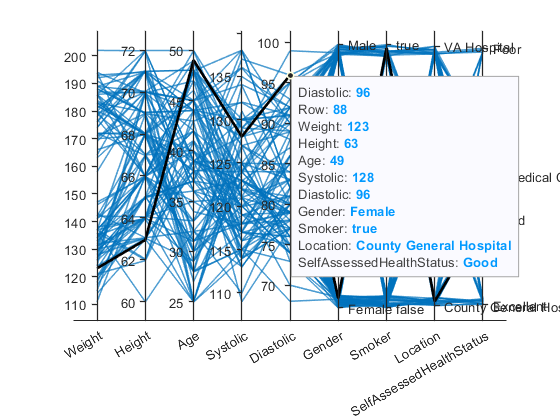

parallelplot(tbl);

Values for each variable are plotted as points on the corresponding vertical axis. Points corresponding to the same observation are connected to the other axes by lines, so that each observation is mapped to a 'path' through the axes. Parallel plots are often noisy but can be interpreted as follows:

- The distribution of values for each variable is determined by the location and density of paths crossing the corresponding axis.

- Potential relationships between variables and observations are indicated by distinct patterns and clusters of paths. 

Note that you can click into the plot to highlight individual paths (observations). 

### Customizing parallel coordinate plots

Parallel coordinate plots convey a lot of information at once. The following methods can help make them easier to interpret:

- Using discrete variables as group variables can reduce the number of axes and help you identify potential reasons for any relationships you observe. 

- Adding normalization can reduce the impact of widely differing variable scales or outliers. See the documentation for more information about the available normalization methods.

- Adjusting plot parameters such as line width and alpha (transparency) can make it easier to follow observations across the plot by reducing crowding.

- Shuffling the axes order can help uncover relationships between a group of variables that may not be apparent if their axes are separated by other variables.

Use the controls below to select a group variable, a data normalization method, and to adjust the plot properties. Code has also been added to shuffle the axes order each time the plot is created, so try rerunning the code several times to see if you notice anything new.

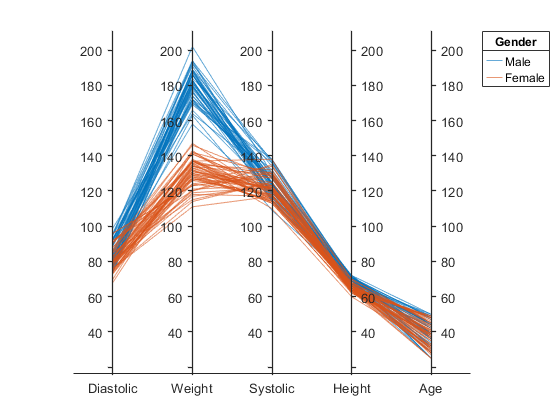

parallelplot(tbl,"CoordinateVariables",contvars(randperm(length(contvars))),...
                 'GroupVariable','Gender',...
                 'DataNormalization',"none",...
                 "LineAlpha",0.6,...
                 "LineWidth",0.5);

What combinations make the parallel plot easier to interpret for this dataset? Can you observe any relationships between variables or clustering of values? 